# Evaluación 11.2

Plameación de trayectorias

Angel Estrada Centeno - A10732584

%% Evaluación 11.2 - Código de ejecución
% Pure Pursuit algorithm
%
% Copyright 2018-2019 The MathWorks, Inc.

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.01;               % Sample time [s]
tVec = 0:sampleTime:59;         % Time array

initPose = [0.27;0.66;pi/2];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [0.27,0.66; 
             -0.12,1.36; 
             -0.38,1.83; 
             -0.46,2.59; 
             -0.21,2.34;
             -0.16,1.74;
             -0.12,1.36;
             -0.38,1.83;
             -0.47,2.59
             -0.26,2.78; 
             -0.29,3.24; 
             -0.26,3.69; 
             -0.07,4.45; 
             0,5; 
             0.49,5.40; 
             0.86,5.77; 
             1.55,6.02; 
             2.17,5.89; 
             2.74,5.66;
             3.42,5.37;
             3.69,4.94;
             3.95,4.37;
             3.92,3.78;
             3.94,3.13;
             3.79,2.62;
             3.26,3.01;
             2.69,3.32;
             2.29,3.13;
             1.29,3.17;
             0.85,3.40;
             0.36,3.17;
             0.85,3.02;
             1.60,3.03;
             1.21,2.24;
             1.81,2.40;
             2.45,2.23;
             1.97,3.07;
             2.29,3.13;
             2.74,2.99;
             3.26,3.01;
             3.79,2.62;
             3.81,2.36;
             3.97,2.56;
             3.97,2.05;
             3.71,1.28;
             3.75,1.72;
             3.79,2.17;
             3.81,2.36;
             3.97,2.56;
             3.97,2.05;
             3.71,1.28;
             3.53,0.90;
             2.73,1.29;
             2.11,1.63;
             1.84,1.46;
             1.63,1.63;
             1.05,1.42;
             1.57,1.07;
             2.21,1.12;
             2.73,1.29;
             3.53,0.9;
             3.37,0.67;
             3.01,0.26;
             2.59,0.07;
             2,0;
             1.27,-0.05;
             0.68,0.38;
             0,1;
             -0.12,1.36;
             -0.38,1.83;
             -0.46,2.59
             -0.21,2.45;
             0.01,3.59;
             0.26,3.61;
             0.62,3.92;
             1.49,3.68;
             2.16,3.63;
             3.08,3.76;
             3.36,3.46;
             2.14,3.53;
             1.44,3.56;
             0.4,3.6;
             0.16,3.95;
             0.39,4.47;
             0.69,4.80;
             0.63,5.18;
             0.32,5;
             0.58,4.73;
             1.08,4.98;
             1.29,5.28;
             1.20,5.56;
             0.49,5.09;
             0.94,4.94;
             1.50,5.09;
             1.89,5.26;
             2.01,5.62;
             1.13,5.29;
             1.79,5.10;
             2.15,5.06;
             2.54,5.19;
             2.5,5.5;
             2.0,5.49;
             2.5,5;
             2.82,4.77;
             3.16,4.94;
             3.11,5.27;
             2.39,5.33;
             3.00,4.61;
             3.5,4.5;
             3.1,4.7;
             3.22,4.48;
             3.43,4.11];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.15;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 15.5;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end

Este algoritmo basado en el recorrido de way-points dibuja mi rostro basado en los puntos calculados manualmente con la herramienta Geo-Gebra:

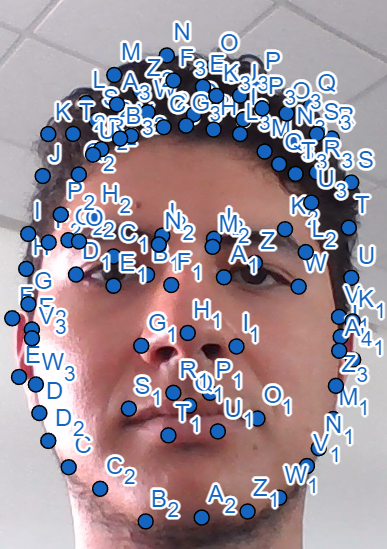

Se utilizaron 112 puntos en total en formato (x,y), los cuales funcionan como los waypoints del robot. Cada punto se colocó a una distancia que no fuera muy lejana entre sí para no perder definición de la imagen, pero tampoco están muy pegados entre sí porque eso aumentaría demasiado la cantidad de puntos por poner manualmente en el programa. Se delimitaron claramente los razgos faciales más importantes como los ojos, orejas, labios, cejas, nariz y cabello.

Resultado:

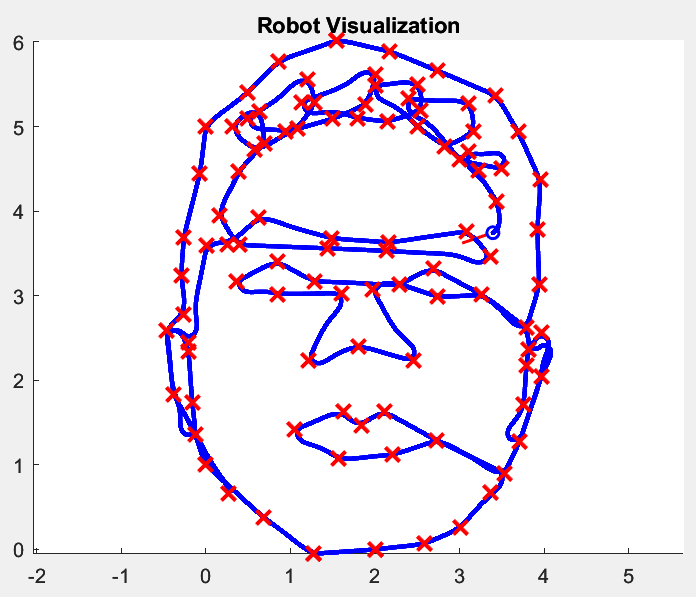

El tiempo de muestreo es de 0.01 segundos para aumentar la definición de los trazos del robot, el tiempo total de ejecución es de 63 segundos; además de esos parámetros, solo se modificaron los waypoints en el arreglo del mismo nombre. 